close all
clear all


all_points = readmatrix('./paths/chelm.txt');

s = 10;
r = (max(all_points(:,2)) - min(all_points(:, 2))) * (s/100);
n = [5 10 15 30];


for i = 1:4
    subplot(2,2,i);
    fig = plot(all_points(:,1), all_points(:, 2));
    x_lim_orig = xlim;
    y_lim_orig = ylim;
    hold on
    
    X = all_points(floor(linspace(1, size(all_points, 1), n(i))), 1);
    Y = all_points(floor(linspace(1, size(all_points, 1), n(i))), 2) + (rand(n(i), 1)-0.5) * r;
    [X_app, Y_app] = poly_app(X, Y, all_points, n(i));
    plot(X_app, Y_app);
    xlim(x_lim_orig);
    ylim(y_lim_orig);
    xlabel('Dystans');
    ylabel('Wysokość');
    title(strcat('Profil wysokościowy dla n=', num2str(n(i))));
    
    X = all_points(floor(linspace(1, size(all_points, 1), n(i))), 1);
    Y = all_points(floor(linspace(1, size(all_points, 1), n(i))), 2);
    [X_app, Y_app] = poly_app(X, Y, all_points, n(i));
    plot(X_app, Y_app);
    title(strcat('Profil wysokościowy dla n=', num2str(n(i))));
    legend('Rzeczywiste', strcat('Z szumem', ' ', num2str(s), '%'), 'Bez szumu');
end

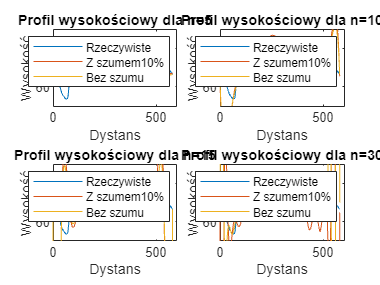


hold off



%hold on
%plot(X_app, Y_app);
%;
%xlim(x_lim_orig);
%ylim(y_lim_orig);

%legend('Dane prawdziwe', 'Przybliżenie');




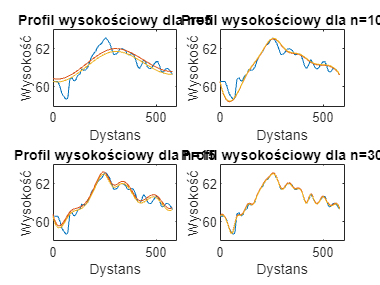

close all
clear all


all_points = readmatrix('./paths/chelm.txt');

s = 10;
r = (max(all_points(:,2)) - min(all_points(:, 2))) * (s/100);


n = [5 10 15 30];

for i = 1:4
    subplot(2,2,i);
    plot(all_points(:,1), all_points(:, 2))
    x_lim_orig = xlim;
    y_lim_orig = ylim;
    hold on
    
    x = all_points(floor(linspace(1, size(all_points, 1), n(i))), 1);
    y = all_points(floor(linspace(1, size(all_points, 1), n(i))), 2) + (rand(1, 1)-0.5) * r;
    [x_app, y_app] = spline_app(x, y, all_points, n(i));
    plot(x_app, y_app);
    xlim(x_lim_orig);
    ylim(y_lim_orig);
    xlabel('Dystans');
    ylabel('Wysokość');
    title(strcat('Profil wysokościowy dla n=', num2str(n(i))));
    
    x = all_points(floor(linspace(1, size(all_points, 1), n(i))), 1);
    y = all_points(floor(linspace(1, size(all_points, 1), n(i))), 2);
    [x_app, y_app] = spline_app(x, y, all_points, n(i));
    plot(x_app, y_app);

    %legend('Rzeczywiste', strcat('Z szumem', ' ', num2str(s), '%'), 'Bez szumu');
end

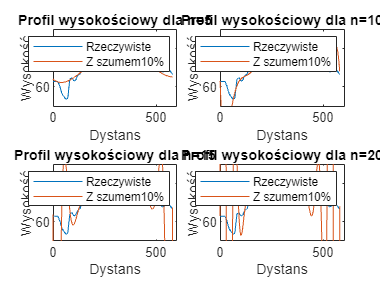


clear all
close all 
clc

all_points = readmatrix('./paths/chelm.txt');


n = [5 10 15 20];

for i = 1:4
    subplot(2,2,i);
    plot(all_points(:,1), all_points(:, 2))
    x_lim_orig = xlim;
    y_lim_orig = ylim;
    hold on
    
    x = floor(linspace(1, size(all_points, 1), n(i)));
    
    for j=1:n(i)
        X(j) = all_points(x(j), 1);
        Y(j) = all_points(x(j), 2);
    end

    %plot(X, Y,'xr');
    
    [X_app, Y_app] = poly_app(X', Y', all_points, n(i));
    plot(X_app, Y_app);
    xlim(x_lim_orig);
    ylim(y_lim_orig);
    xlabel('Dystans');
    ylabel('Wysokość');
    title(strcat('Profil wysokościowy dla n=', num2str(n(i))));
    
end


n = 100;

x = 1:1:n;

m = size(x, 2);

%plot(x, zeros(1,m),'xr')